Aqui se realizaran las pruebas para los metodos de encontrar raices 

cosas a arreglar

- eliminar la variable global sol1 de todos los metodos

- la numeracion en cada matriz de resultados esta mal

- el metodo de punto fijo no funciona

- documentar todas las funciones

close all
f = @(x) 4.56*10^-8*x^4+34.625*x-16366.79156

f = function_handle with value:
    @(x)4.56*10^-8*x^4+34.625*x-16366.79156


fsym = sym(f)

$$fsym = \frac{3445438585901693\,x^{4}}{75557863725914323419136}+\frac{277\,x}{8}-\frac{8997738814803049}{549755813888}$$





resultados = biseccion(400,500,100,0.0001,fsym)

resultados =          0  450.0000         0
    1.0000  425.0000   25.0000
    2.0000  437.5000   12.5000
    3.0000  431.2500    6.2500
    4.0000  428.1250    3.1250
    5.0000  429.6875    1.5625
    6.0000  428.9062    0.7812
    7.0000  428.5156    0.3906
    8.0000  428.3203    0.1953
    9.0000  428.4180    0.0977


sol1 = resultados(end,2)

sol1 = 428.3498

x1=[0,numel(resultados(:,1))-1]

x1 =      0    19


y1=[sol1,sol1]

y1 =   428.3498  428.3498


x2=sol1(1)-0.75*abs(sol1(1)):0.01:sol1(1)+0.75*abs(sol1(1))

x2 =   107.0874  107.0974  107.1074  107.1174  107.1274  107.1374  107.1474  107.1574  107.1674  107.1774  107.1874  107.1974  107.2074  107.2174  107.2274  107.2374  107.2474  107.2574  107.2674  107.2774  107.2874  107.2974  107.3074  107.3174  107.3274  107.3374  107.3474  107.3574  107.3674  107.3774  107.3874  107.3974  107.4074  107.4174  107.4274  107.4374  107.4474  107.4574  107.4674  107.4774  107.4874  107.4974  107.5074  107.5174  107.5274  107.5374  107.5474  107.5574  107.5674  107.5774


y2=double(subs(fsym,symvar(fsym),x2))

y2 = 1.0e+04 *

   -1.2653   -1.2653   -1.2652   -1.2652   -1.2651   -1.2651   -1.2651   -1.2650   -1.2650   -1.2650   -1.2649   -1.2649   -1.2649   -1.2648   -1.2648   -1.2648   -1.2647   -1.2647   -1.2647   -1.2646   -1.2646   -1.2646   -1.2645   -1.2645   -1.2645   -1.2644   -1.2644   -1.2643   -1.2643   -1.2643   -1.2642   -1.2642   -1.2642   -1.2641   -1.2641   -1.2641   -1.2640   -1.2640   -1.2640   -1.2639   -1.2639   -1.2639   -1.2638   -1.2638   -1.2638   -1.2637   -1.2637   -1.2637   -1.2636   -1.2636


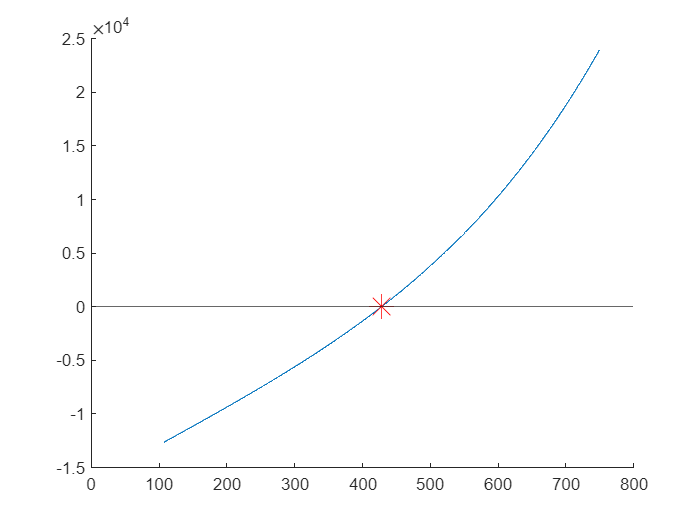

hold on
plot(x2,y2)

plot(sol1,0,"Color",'r',"Marker","*","MarkerSize",15)
xline(0)
yline(0)

hold off

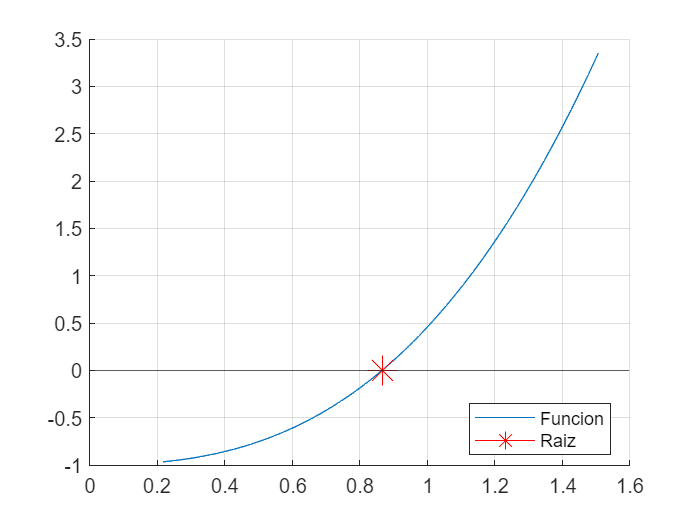

ans =                    0                   0                   0
   1.000000000000000   0.500000000000000   0.500000000000000
   2.000000000000000   0.750000000000000   0.250000000000000
   3.000000000000000   0.875000000000000   0.125000000000000
   4.000000000000000   0.812500000000000   0.062500000000000
   5.000000000000000   0.843750000000000   0.031250000000000
   6.000000000000000   0.859375000000000   0.015625000000000
   7.000000000000000   0.867187500000000   0.007812500000000
   8.000000000000000   0.863281250000000   0.003906250000000
   9.000000000000000   0.865234375000000   0.001953125000000


biseccion(-1,1,10,0.001,fsym)